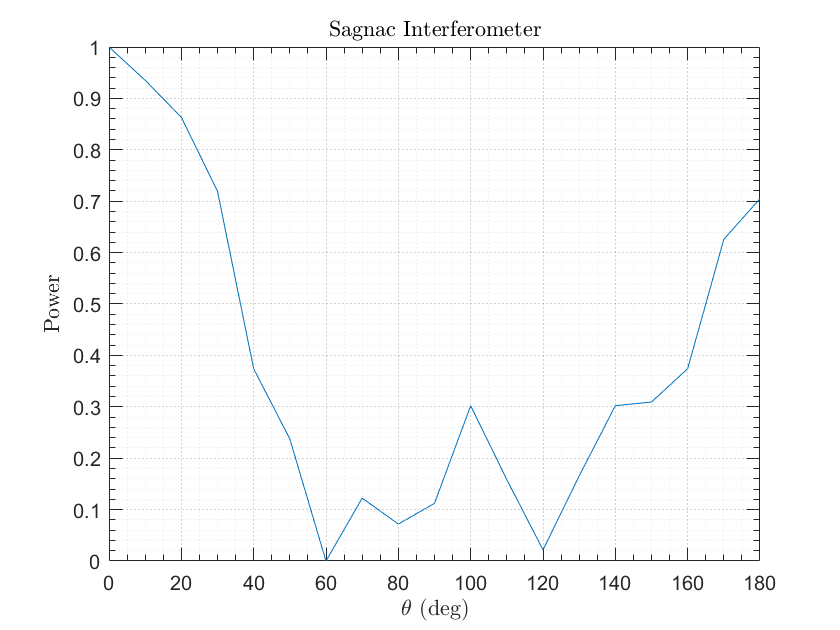

theta = 0:10:180;
P = [18.5*1e3, 17.6*1e3, 16.6*1e3, 14.6*1e3, 9.8*1e3, 7.9*1e3, 4.6*1e3, 6.3*1e3, 5.6*1e3, 6.16*1e3, 8.8*1e3, 6.8*1e3, 4.9*1e3, 6.9*1e3, 8.8*1e3, 8.9*1e3, 9.8*1e3, 13.3*1e3, 14.4*1e3];
P = normData(P);
plot(theta, P)
xlabel('$\theta$ (deg)', "Interpreter","latex");
ylabel('Power', "Interpreter","latex");
title('Sagnac Interferometer', "Interpreter", "latex");
grid on
set(gca, 'XMinorTick', 'on', 'YMinorTick', 'on', ...
'TickLength', [0.02, 0.04], ...
'LineWidth', 0.5);
grid minor; % Adds minor grid lines
set(gca, 'GridLineStyle', ':', ...    % Dashed grid lines
         'GridColor', [0.5, 0.5, 0.5], ... % Gray grid lines
         'GridAlpha', 0.7, ...         % Transparency of major grid
         'MinorGridLineStyle', ':', ...% Dotted minor grid lines
         'MinorGridColor', [0.8, 0.8, 0.8], ... % Light gray minor grid
         'MinorGridAlpha', 0.5);       % Transparency of minor grid

function ND = normData(x)
    ND = (x - min(x))/(max(x) - min(x));
end